# Image Encryption using VCS and LSB Watermarking Algo 2

clc;
clear;
close all;

## Visual Cryptography

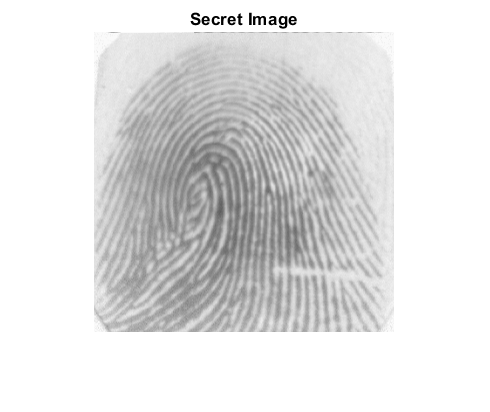

% Read Input Secret (fingerprint) Image

inImg = imread('102_3.tif');
figure;
imshow(inImg);title('Secret Image');

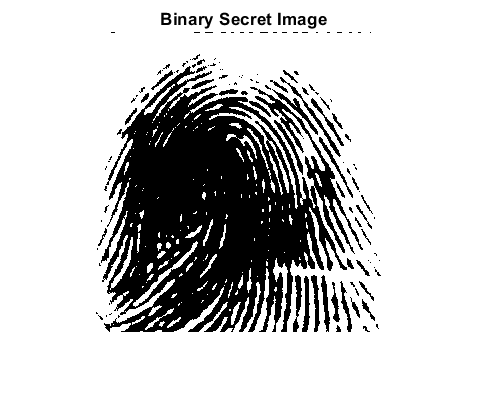

% Convert Secret Image to Binary

inImg = imbinarize(inImg);
figure;
imshow(inImg);title('Binary Secret Image');

% Perform Visual Cryptography
tic;
[share1, share2] = VisualCryptography(inImg);

White Pixel Processing...
Black Pixel Processing...
Share Generation Completed.


t1 = toc;
disp("VCS Encryption")

VCS Encryption


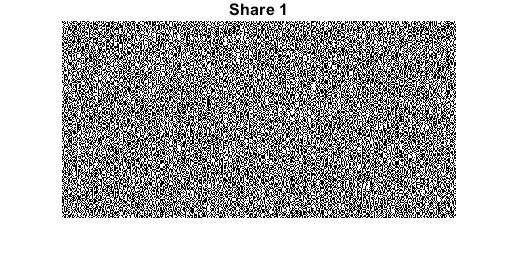

figure;imshow(share1);title('Share 1');

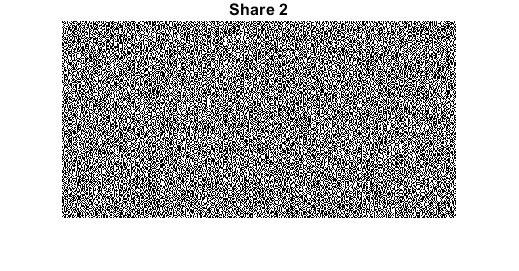

figure;imshow(share2);title('Share 2');

% Save the shares
disp('Saving.....')

Saving.....


imwrite(share1,'Share1.tif');
imwrite(share2,'Share2.tif');
disp('Done')

Done


## LSB Watermarking

% LSB Watermarking of Share 2
disp('Performing LSB watermarking')

Performing LSB watermarking


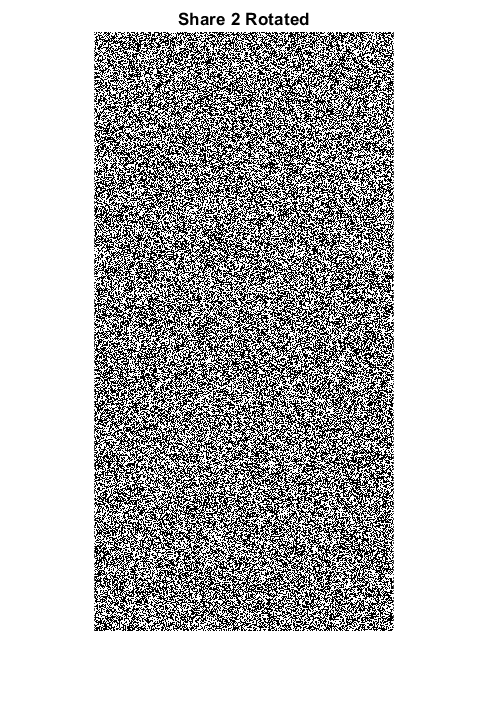

employee = 123456789;

% reshape to portrait
s = size(share2);
share2 = reshape(share2,[s(2),s(1)]);
share2 = imbinarize(share2);
figure;imshow(share2);title('Share 2 Rotated');

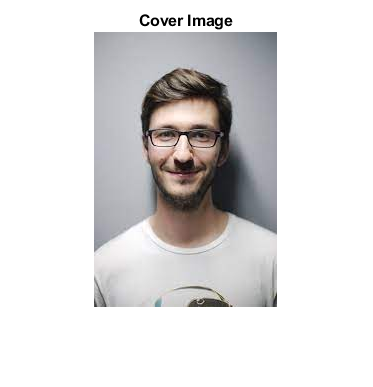

% Get Photo and resize it
face = imread('face.jpeg');
s = size(share2);
figure;imshow(face);title('Cover Image');

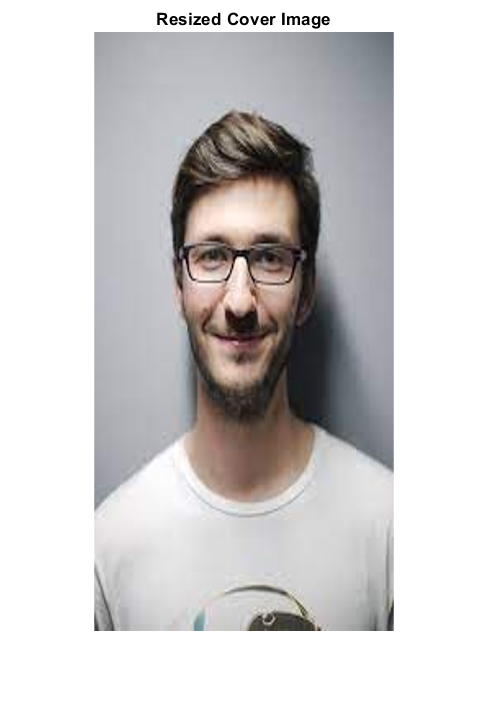

face = imresize(face,s);
figure;imshow(face);title('Resized Cover Image');

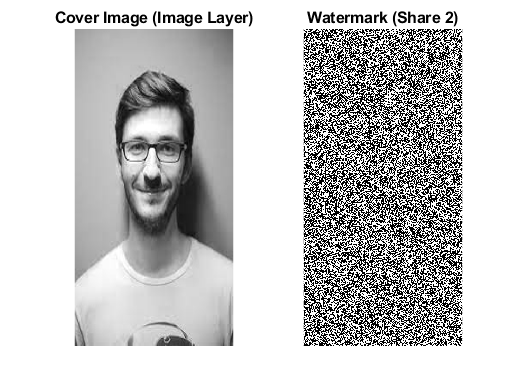

% Get the layer in which share will be hidden
x =  rem(employee,3)+1;
layer = face(:,:,x);
figure;subplot(121);imshow(layer);title('Cover Image (Image Layer)'); 
       subplot(122);imshow(share2);title('Watermark (Share 2)');

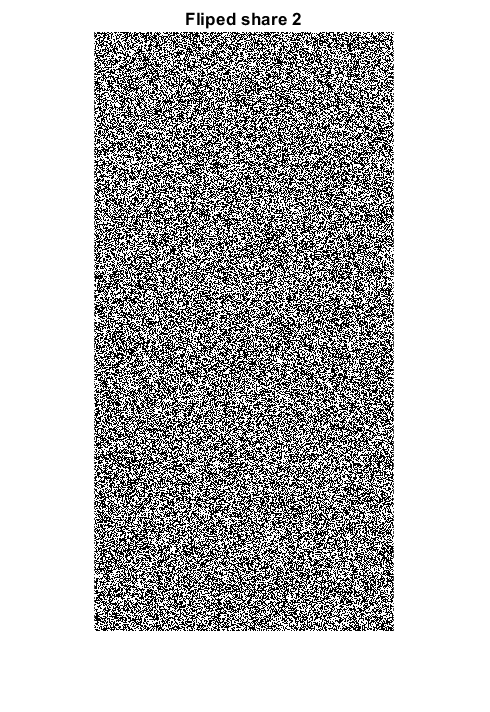

% least significant bit substitution
tic;
share2_flip = fliplr(share2);
t2 = toc;
figure;imshow(share2_flip);title(['Fliped share 2']); 


disp("fliped share")

fliped share


disp(share2(1,end-5:end))

   0   0   0   1   1   0



disp("share")

share


disp(share2_flip(1,1:6))

   0   1   1   0   0   0



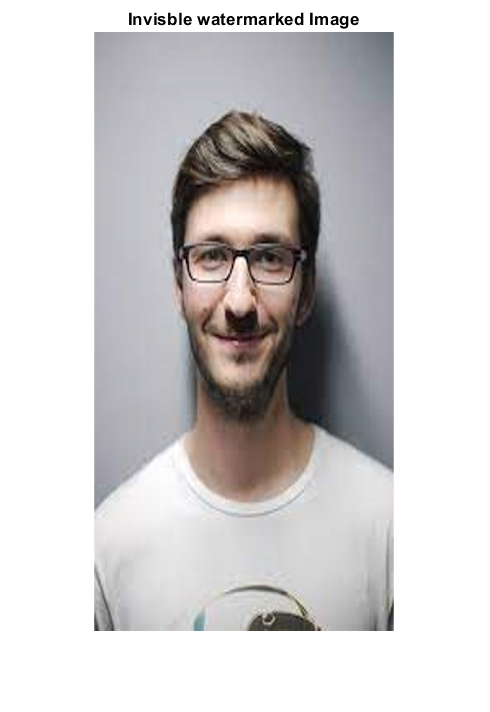


tic;
z=double(share2_flip);
r=double(layer-mod(layer,2)); % removal of LSB bits 
l=uint8(r+z);

face(:,:,x) = l;
t3=toc;

figure;imshow(face);title('Invisble watermarked Image'); 

disp('Lsb wartermarking done')

Lsb wartermarking done


% Saving watermarked image
disp('Saving watermarked image')

Saving watermarked image


imwrite(face,'face.tif');
disp('Done')

Done


time  = t1 + t2 + t3;
disp("Time take for LSB 2 Encryption")

Time take for LSB 2 Encryption


disp(time)

    0.9132



function [share1, share2] = VisualCryptography(inImg)
s = size(inImg);
share1 = zeros(s(1), (2 * s(2)));
share2 = zeros(s(1), (2 * s(2)));

% White Pixel Processing
disp('White Pixel Processing...');
% White Pixel share combinations

s1a=[1 0];
s1b=[1 0];
[x , y] = find(inImg == 1);
len = length(x);
for i=1:len
    a=x(i);b=y(i);
    pixShare=ShareGenerator(s1a,s1b);
    share1((a),(2*b-1):(2*b))=pixShare(1,1:2);
    share2((a),(2*b-1):(2*b))=pixShare(2,1:2);
end
% Black Pixel Processing
disp('Black Pixel Processing...');
% Black Pixel share combinations

s0a=[1 0];
s0b=[0 1];
[x ,y] = find(inImg == 0);
len = length(x);
for i=1:len
    a=x(i);b=y(i);
    pixShare=ShareGenerator(s0a,s0b);
    share1((a),(2*b-1):(2*b))=pixShare(1,1:2);
    share2((a),(2*b-1):(2*b))=pixShare(2,1:2);
end
disp('Share Generation Completed.');
end
    
function out = ShareGenerator(a,b)
a1 = a(1);
a2 = a(2);
b1 = b(1);
b2 = b(2);
in = [a
      b];
out = zeros(size(in));
randNumber = randi([0,1]);
if (randNumber == 0)
    out = in;
elseif (randNumber == 1)
    a(1) = a2;
    a(2) = a1;
    b(1) = b2;
    b(2) = b1;
    out = [a
           b];   
end

end
